clc
clear

close all

% Part 1: Raised-Cosine Pulse Generation

B = 0; 
T = 1;
Fs = 10;
Ts = 1;
L = T*Fs;
[~, RC] = RC_pulse(T, Fs, B);

% Part 2: Creating Modulated Symbols

N = 1e6;

bits = rand(1,N);
SNR_dB = 0:10;

modulated_symbols = zeros(1,length(bits));
SNR = zeros(1,length(SNR_dB)) ;

for i = 1 : length(bits)
    if (bits(i)<0.1 && bits(i)>=0)
        modulated_symbols(i) = -3;
    end
    if (bits(i)>=0.1 && bits(i)<0.5)
        modulated_symbols(i) = -1;
    end
    if (bits(i)>=0.5 && bits(i)<0.9)
        modulated_symbols(i) = 1;
    end
    if (bits(i) >= 0.9 && bits(i) < 1)
        modulated_symbols(i) = 3;
    end
end

% Part 3: Transmission and Reception

temp = upsample(modulated_symbols,L);
temp = temp(1:end-(L-1));
transmitted_signal = conv(temp,RC);
noise = randn(1,length(transmitted_signal));

SNR_dB = 0:10;
snr = 10.^(SNR_dB./10);
eta = var(transmitted_signal)./snr;
noise = diag(sqrt(eta./2))*repmat(noise,11,1);
received_signal = repmat(transmitted_signal,11,1)+ noise;

% Part 4: ML detection:
T_sampling = 6*L+1 : L : (N+6-1)*L+1;
samples = received_signal(:,T_sampling);
detected_symbols_ML = zeros(size(samples));
for i = 1 : length(SNR_dB)
    for j = 1 : length(samples)
        if (samples(i,j) <= -2)
            detected_symbols_ML(i,j) = -3;
        end
        if (samples(i,j) > -2 && samples(i,j) <= 0)
            detected_symbols_ML(i,j) = -1;
        end
        if (samples(i,j) > 0 && samples(i,j) <= 2)
            detected_symbols_ML(i,j) = 1;
        end
        if (samples(i,j) > 2)
            detected_symbols_ML(i,j) = 3;
        end
    end
end

error_ML = zeros(1,length(SNR_dB));
for i = 1 : length(SNR_dB)
    for j = 1:length(detected_symbols_ML)
        if detected_symbols_ML(i,j) ~= modulated_symbols(j)
            error_ML(i)=error_ML(i)+1;
        end
    end
end
Pe_ML = reshape(error_ML, [1 11])/N;

% Part 5: MAP detection:

delta_1_MAP = -0.5*eta/2*log2(4)-2;
delta_2_MAP = [0 0 0 0 0 0 0 0 0 0 0];
delta_3_MAP = 0.5*eta/2*log2(4)+2;
detected_symbols_MAP = zeros(size(samples));

for i = 1 : length(SNR_dB)
    for j = 1 : length(samples)
        if (samples(i,j) <= delta_1_MAP(i))
            detected_symbols_MAP(i,j) = -3;
        end
        if (samples(i,j) > delta_1_MAP(i) && samples(i,j) <= delta_2_MAP(i))
            detected_symbols_MAP(i,j) = -1;
        end
        if (samples(i,j) > delta_2_MAP(i) && samples(i,j) <+ delta_3_MAP(i))
            detected_symbols_MAP(i,j) = 1;
        end
        if (samples(i,j) > delta_3_MAP(i))
            detected_symbols_MAP(i,j) = 3;
        end
    end
end

error_MAP = zeros(1,length(SNR_dB));
for i = 1 : length(SNR_dB)
    for j = 1:length(detected_symbols_MAP)
        if detected_symbols_MAP(i,j) ~= modulated_symbols(j)
            error_MAP(i)=error_MAP(i)+1;
        end
    end
end
Pe_PAM = reshape(error_MAP, [1 11])/N;

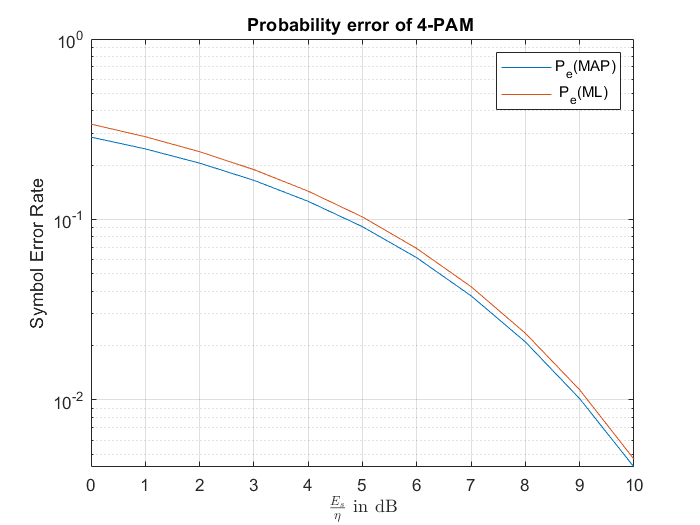

% Part 6: Plotting Results:

figure
semilogy(SNR_dB,Pe_PAM,SNR_dB,Pe_ML)
grid on
title('Probability error of 4-PAM ' )
xlabel('$\frac{E_{s}}{\eta}$ in dB', 'interpreter', 'Latex');
ylabel('Symbol Error Rate')
legend('P_{e}(MAP)',' P_{e}(ML)')